clc;
clear;
close all;

rawData = readlines("dataset.txt");

n = numel(rawData);
sentences = strings(n,1);
labels = categorical(strings(n,1));  % Preallocate

for i = 1:n
    parts = split(rawData(i), char(9));  % Split by tab
    sentences(i) = strtrim(parts(1));
    disp(sentences(i));
    if strtrim(parts(2)) == "1"
        labels(i) = "positive";
    else
        labels(i) = "negative";
    end
end

So there is no way for me to plug it in here in the US unless I go by a converter.
Good case, Excellent value.
Great for the jawbone.
Tied to charger for conversations lasting more than 45 minutes.MAJOR PROBLEMS!!
The mic is great.
I have to jiggle the plug to get it to line up right to get decent volume.
If you have several dozen or several hundred contacts, then imagine the fun of sending each of them one by one.
If you are Razr owner...you must have this!
Needless to say, I wasted my money.
What a waste of money and time!.
And the sound quality is great.
He was very impressed when going from the original battery to the extended battery.
If the two were seperated by a mere 5+ ft I started to notice excessive static and garbled sound from the headset.
Very good quality though
The design is very odd, as the ear "clip" is not very comfortable at all.
Highly recommend for any one who has a blue tooth phone.
I advise EVERYONE DO NOT BE FOOLED!
So Far So Good!.
Works great!.
It clicks into

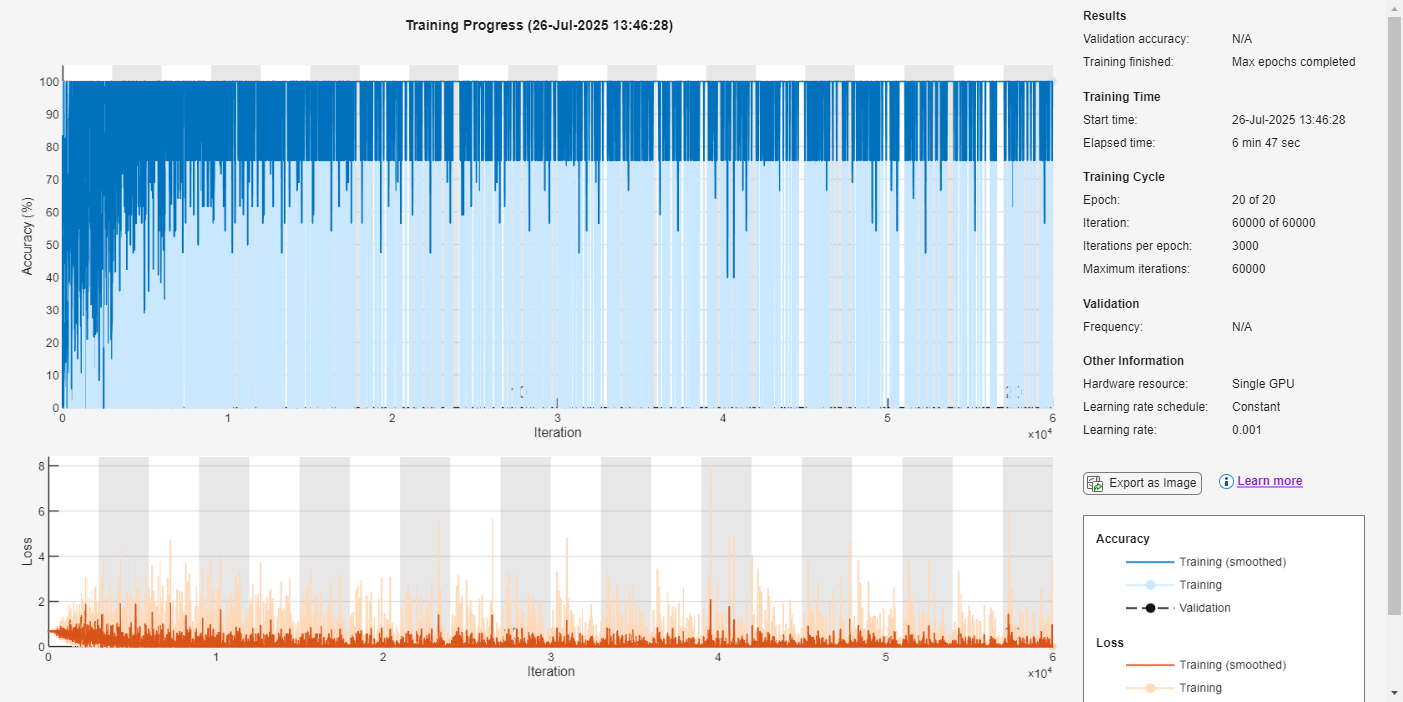


% Tokenize & preprocess
documents = tokenizedDocument(sentences);
documents = erasePunctuation(documents);
documents = removeStopWords(documents);

% Bag of Words to features
bag = bagOfWords(documents);
X = full(bag.Counts);     % Convert to full matrix
Y = categorical(labels);  % Ensure categorical labels

% Train entire set (no split, small dataset)
layers = [
    featureInputLayer(size(X,2))
    fullyConnectedLayer(10)
    reluLayer
    fullyConnectedLayer(2)
    softmaxLayer
    classificationLayer];

options = trainingOptions('adam', ...
    'MaxEpochs', 20, ...
    'MiniBatchSize', 1, ...
    'Verbose', false, ...
    'Plots', 'training-progress');

net = trainNetwork(X, Y, layers, options);